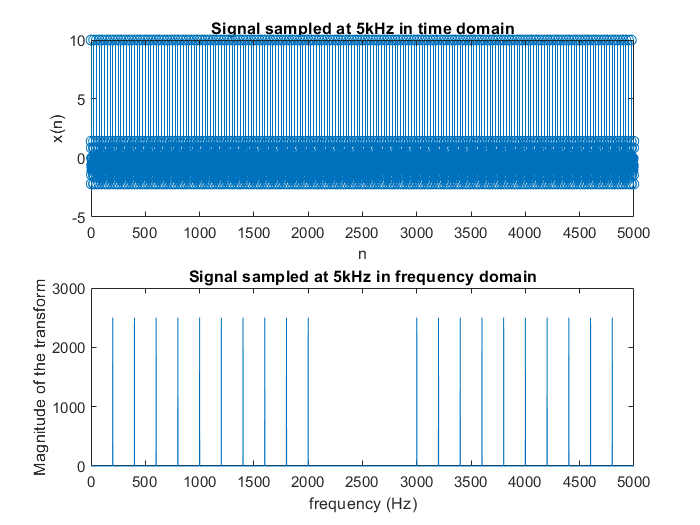

clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

signal_supersition = sum(x, 1);
subplot(2,1,1);
stem(n, signal_supersition);
% stem(n*T, signal_supersition);
xlabel('n');
ylabel('x(n)');
title('Signal sampled at 5kHz in time domain');
% soundsc(signal_supersition);

fft_for_signal = fft(signal_supersition);
f = 0:4999;
subplot(2,1,2);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude of the transform');
title('Signal sampled at 5kHz in frequency domain');
hold off;

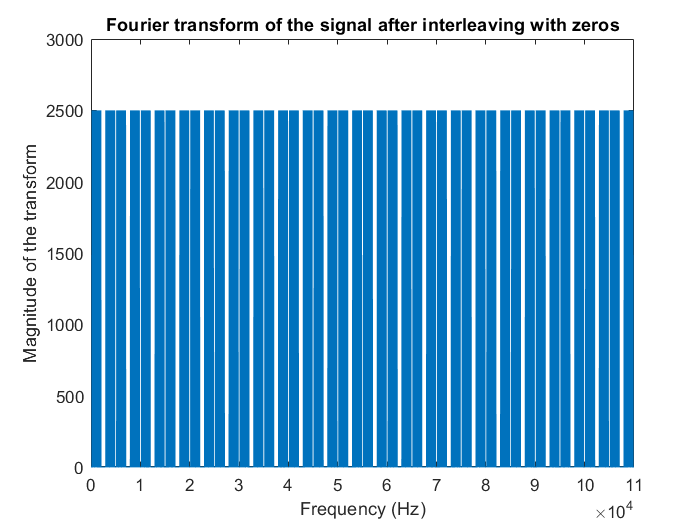

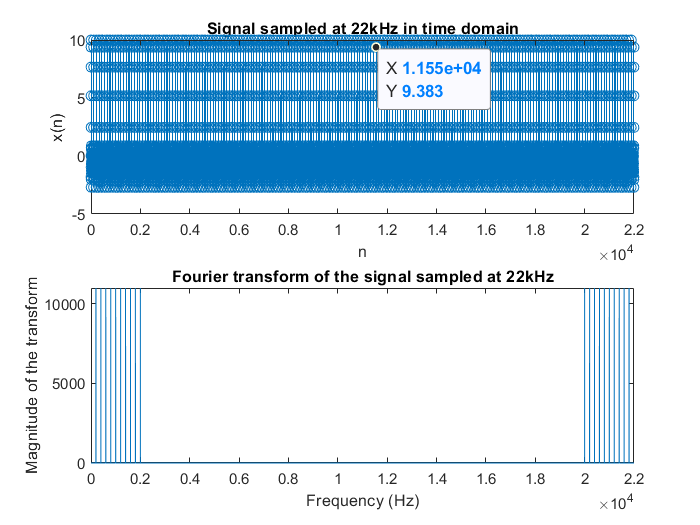

% Read the audio file into workspace.
[samples_of_the_filter, fs_of_filter] = audioread('telephoneIR.wav');

% First in order to do convolution operation to original signal and filter,
% we have to make their sampling frequency identical, thus resampling the
% original signal to 22kHz, which is the sampling frequency of the filter.
signal_after_resample_22kHz = resample_by_factor_p_over_q(signal_supersition, 22, 5);

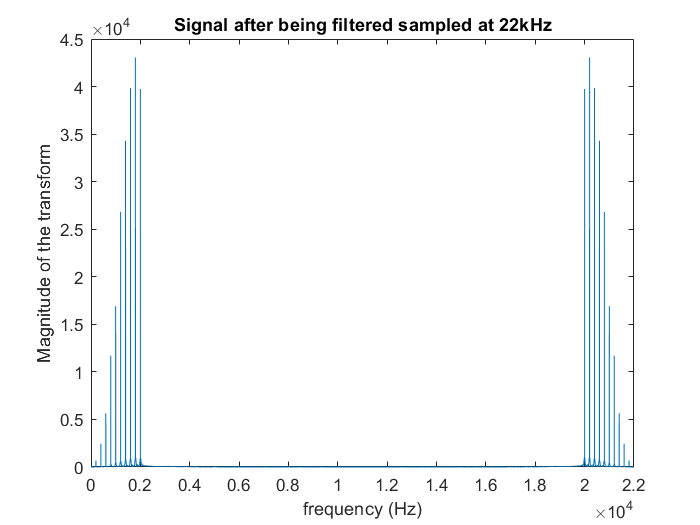

% Convolve the resampled signal with the filter in time domain.
signal_after_being_filtered_22kHz = conv(signal_after_resample_22kHz, samples_of_the_filter','same');
% soundsc(signal_after_being_filtered_22kHz);
% Plot the convolved signal.
fft_for_filter_signal_22kHz = fft(signal_after_being_filtered_22kHz);
figure
k = 0:21999;
plot(k, abs(fft_for_filter_signal_22kHz));
xlabel('frequency (Hz)');
ylabel('Magnitude of the transform');
title('Signal after being filtered sampled at 22kHz');
xlim([0 22000]);
hold off;

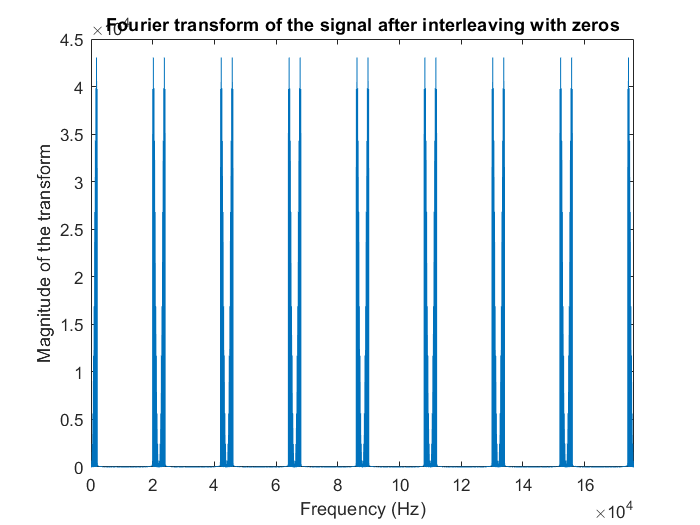

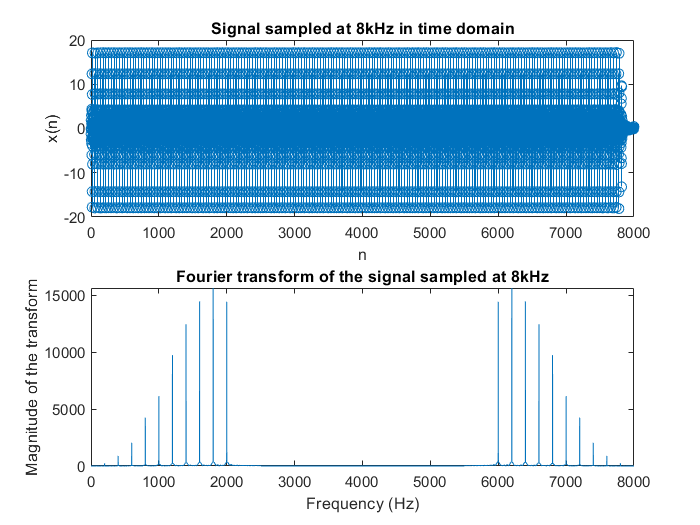

% Resample the convolved signal to sampling frequency of 8kHz.
filtered_signal_resample_to_8kHz = resample_by_factor_p_over_q(signal_after_being_filtered_22kHz, 8, 22);

% soundsc(filtered_signal_resample_to_8kHz);